t = 1:0.05:4

t =     1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500    2.5000    2.5500    2.6000    2.6500    2.7000    2.7500    2.8000    2.8500    2.9000    2.9500    3.0000    3.0500    3.1000    3.1500    3.2000    3.2500    3.3000    3.3500    3.4000    3.4500


f = 0.5

f = 0.5000

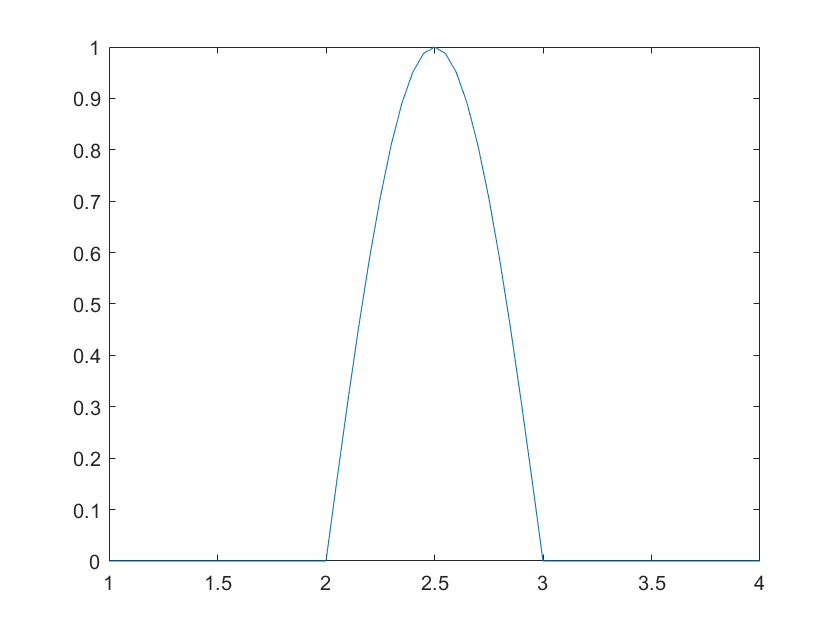

y=sin(2*pi*f*t);% Generate Sine Wave  
y(y<0) = 0;                       % Rectified Sine Wave
plot(t,y);

F = [t
     y]

F =     1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500    2.5000    2.5500    2.6000    2.6500    2.7000    2.7500    2.8000    2.8500    2.9000    2.9500    3.0000    3.0500    3.1000    3.1500    3.2000    3.2500    3.3000    3.3500    3.4000    3.4500
    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.1564    0.3090    0.4540    0.5878    0.7071    0.8090    0.8910    0.9511    0.9877    1.0000    0.9877    0.9511    0.8910    0.8090    0.7071    0.5878    0.4540    0.3090    0.1564    0.0000         0         0         0         0         0         0         0         0     


L1 = 2; 
L2 = 3; 
theta1 = pi; 
theta2 = pi; 

J = jacobian(L1, L2, theta1, theta2)

J =     0.0000    0.0000
    1.0000    3.0000



torque = J\F

torque = 	1.0e+16 *

    0.4083    0.4287    0.4491    0.4695    0.4899    0.5104    0.5308    0.5512    0.5716    0.5920    0.6124    0.6328    0.6532    0.6737    0.6941    0.7145    0.7349    0.7553    0.7757    0.7961    0.8166    0.8370    0.8574    0.8778    0.8982    0.9186    0.9390    0.9595    0.9799    1.0003    1.0207    1.0411    1.0615    1.0819    1.1024    1.1228    1.1432    1.1636    1.1840    1.2044    1.2248    1.2453    1.2657    1.2861    1.3065    1.3269    1.3473    1.3677    1.3882    1.4086
   -0.1361   -0.1429   -0.1497   -0.1565   -0.1633   -0.1701   -0.1769   -0.1837   -0.1905   -0.1973   -0.2041   -0.2109   -0.2177   -0.2246   -0.2314   -0.2382   -0.2450   -0.2518   -0.2586   -0.2654   -0.2722   -0.2790   -0.2858   -0.2926   -0.2994   -0.3062   -0.3130   -0.3198   -0.3266   -0.3334   -0.3402   -0.3470   -0.3538   -0.3606   -0.3675   -0.3743   -0.3811   -0.3879   -0.3947   -0.4015   -0.4083   -0.4151   -0.4219   -0.4287   -0.4355   -0.4423   -0.4491   -0.45

function J = jacobian(L1, L2, theta1, theta2)
    J = [(-L1 * sin(theta1) - L2 * sin(theta1+theta2)) (-L2 * sin(theta1+theta2))
         (L1 * cos(theta1) + L2 * cos(theta1+theta2))  (L2 * cos(theta1+theta2))];
end